# Flight Test Comparison: 

This live script is centered on a comparison between the baseline and adaptive controller in a scenario meant to represent a package delivery mission. First, the capacity of each system in the absence of external perturbations will be assessed. Afterwards, their capacity to react to wind gusts and a sudden degradation of control effectiveness will also be explored. 

addpath("Models and Auxiliary Functions\")
addpath("Trajectory Generation\")

## System Definition and Initialization: 

Common UAV parameters: 

%Specify gravitational acceleration: 
g=9.81; %[m/s^2]

%Geometric and Inertial Properties:
UAV.Nr = 6; %number of rotors
UAV.m = 1.2; %[kg] UAV mass
UAV.J = diag([0.01 0.01 0.018]); % [kg m^2] inertia matrix
UAV.r_bg = [0 0 0]'; %[m] center of mass location in the body frame -> note I change it to a column vector. 
UAV.S = UAV.m*cross_matrix(UAV.r_bg); % [kg m] static moment

% Linear Aerodynamics
UAV.D_tauomega = diag([0.48 0.48 2.37]); %  angular velocity damping 
UAV.D_fv =  diag([0.055 0.055 0.022]); % linear velocity damping
UAV.D = [UAV.D_fv zeros(3,3); zeros(3,3) UAV.D_tauomega]; %-> there is a typo in the position of D_fv and D_tauomega on the data provided by the professor

% Propellers 
UAV.b = 0.215; %[m] arm length (ell in the slides)

k_f = 3.65e-6;                % [N/rad^2/s^2] Thrust characteristic coeff
sigma = 0.09;                 % [m] Torque-to-thrust ratio

%Construct input map:
%Rotors 1,3,5 rotate in the positive direction, 2,4,6 rotate in the
%negative direction
xiv=zeros(UAV.Nr,1);
xiv(1:2:UAV.Nr)=1; 
xiv(2:2:UAV.Nr)=-1;

gamma_r=2*pi/UAV.Nr*(0:UAV.Nr-1);
nr=[0;0;1];

F=nan(6,UAV.Nr);
for i=1:UAV.Nr
    pr=UAV.b*[cos(gamma_r(i));sin(gamma_r(i));0];
    pr_x=cross_matrix(pr);
    F(1:3,i)=nr;
    F(4:6,i)=(pr_x-xiv(i)*sigma*eye(3,3))*nr;
end

UAV.F=F;

%Actuator Dynamics: 
UAV.Omega_max = 10300; %[rpm] max spinning rate
UAV.Omega_min = 1260; %[rpm] min spinning rate
UAV.k_m = 1/0.05; % [s-1] Inverse of the time constant of the propeller motors

T_max=k_f*(UAV.Omega_max*2*pi/60)^2; %Unit conversion needed since kf is in N/(rad^2/s^2) and Omega_max and _min are given in rpm.
T_min=k_f*(UAV.Omega_min*2*pi/60)^2;

%For control allocation: (validated expression for F2 Plus)
F_2=F(3:6,:);
UAV.F_2_Plus=F_2'/(F_2*F_2');

%Define position controller: 
%Performance Goals: 
omega_n_p=1.75; %[rad/s]
zeta_p=0.8;    %[-]

%Convert to tuning: 
kp=omega_n_p^2;
kv=2*zeta_p*omega_n_p;

K_p=kp*eye(3,3);
K_v=kv*eye(3,3);

%Define attitude controller: 
%Tune controller: 
omega_n_a=20; %[rad/s]
zeta_a=1;     %[-]

%Tune k_r
k_r_hat=omega_n_a^2*diag(UAV.J);
A=[0,1,1;1,0,1;1,1,0];
k_r=A\k_r_hat;

%Tune K_omega:
K_omega=2*zeta_a*omega_n_a*UAV.J;

Common package parameters:

%Define package position and inertial parameters:
UAV.m_p=0.4; %[kg]
UAV.J_p=diag([0.01,0.01,0.01]); %[kg*m^2]
UAV.r_c=[0;0;-0.3]; %[m] distance between UAV's CoG and package's CoG -> 30 cm
UAV.m_t=UAV.m+UAV.m_p;
UAV.S_t=UAV.S+UAV.m_p*cross_matrix(UAV.r_c); %[kg*m]
UAV.J_t=UAV.J+UAV.J_p+UAV.m_p*(UAV.r_c'*UAV.r_c*eye(3,3)-UAV.r_c*UAV.r_c'); %[kg*m^2]

UAV.MM=[UAV.m_t*eye(3,3),UAV.S_t';UAV.S_t,UAV.J_t];
UAV.MM_inv=inv(UAV.MM);

Adaptive Controller Definition: 

%For predictor dynamics: 
A_p=[zeros(3,3),eye(3,3);zeros(3,3),zeros(3,3)];
B_p=[zeros(3,3);eye(3,3)];
B_pT=B_p';

%Tune adaptive controller: 
L=100*eye(6,6);
Gamma_a=20*eye(6,6);

%Define minimum lambda for smart integrator: 
lambda_min=0.1; 

%Define variables needed for projection operator: 
epsilon=0.1; %leaves 95% of the range unaffected
lambda_max=2;
a_e_tilde_max=g;

Load trajectory information: 

load("trajectory.mat")
map3D=importOccupancyMap3D("map3D.ot");

Initialize system parameters: 

%Initialize system: consider it starting from a trim condition at
%startState
%Initialize postion and kinematics: 
p_b_i_0=startState';
q_0=[1;0;0;0];
v_b_0=[0;0;0];
omega_b_0=[0;0;0];
nu_b_0=[v_b_0;omega_b_0];

%Initialize rotor angular velocities: trim without the package!
T_0=UAV.m*g/UAV.Nr; 
Omega_r_0=sqrt(T_0/k_f)*ones(UAV.Nr,1);

Initialize adaptive controller: 

%Initialize adaptive laws: 
lambda_hat_0=[1;1;1];
a_e_tilde_hat_0=[0;0;0];


%Initialize predictor: 
p_i_hat_0=p_b_i_0;
v_i_hat_0=[0;0;0];
x_hat_0=[p_i_hat_0;v_i_hat_0];

## Baseline Controller in Nominal Conditions: 

#### Flight Simulation: 

Specify nominal conditions: 

%Turn off switches
degradation_switch=0;
wind_switch=0;
Lambda_deg=eye(6,6);
t_deg=1;
w_intensity=0;

%Specify baseline Lambda:
Lambda_baseline=eye(6,6);

Simulate flight: 

simout=sim("Flight_Test_Baseline_Model.slx","StopTime",'55','RelTol','1e-6');

#### Simulation Postprocessing: 

Begin by plotting the desired and flown trajectories together for a qualitative assessment. 

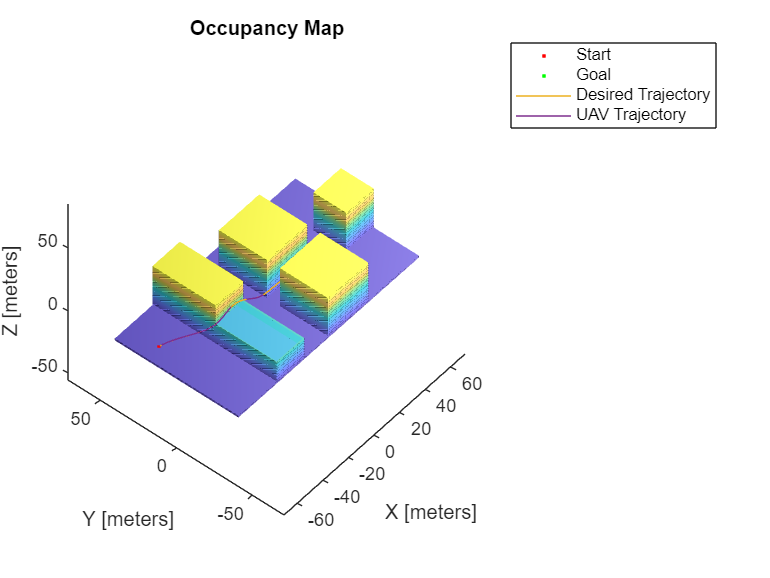

%System trajectory:
system_trajectory=nan(3,length(simout.p_b_i.time));
system_velocity=nan(3,length(simout.v_i.time));
for i=1:length(simout.p_b_i.time)
    system_trajectory(:,i)=simout.p_b_i.data(:,1,i);
    system_velocity(:,i)=simout.v_i.data(:,1,i);
end

%Desired trajectory
desired_trajectory=nan(3,length(simout.p_d.time));
desired_velocity=nan(3,length(simout.v_d.time));
for i=1:length(simout.p_b_i.time)
    desired_trajectory(:,i)=simout.p_d.data(:,1,i);
    desired_velocity(:,i)=simout.v_d.data(:,1,i);
end

figure
clf 
show(map3D)
hold on 
scatter3(startState(1),startState(2),startState(3),30,".r")
scatter3(goalState(1),goalState(2),goalState(3),30,".g")
plot3(desired_trajectory(1,:),desired_trajectory(2,:),desired_trajectory(3,:))
plot3(system_trajectory(1,:),system_trajectory(2,:),system_trajectory(3,:))
legend("","Start","Goal","Desired Trajectory","UAV Trajectory")

Provide a quantitative assessment of the error in position and velocity. 

T=55; %[s] Simulation time
pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    pos_integrand(i)=(system_trajectory(:,i)-desired_trajectory(:,i))'*(system_trajectory(:,i)-desired_trajectory(:,i));
end

for i=1:length(simout.v_i.time)
    vel_integrand(i)=(system_velocity(:,i)-desired_velocity(:,i))'*(system_velocity(:,i)-desired_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.0989

display(vel_Error)

vel_Error = 0.0867

The baseline system will, in nominal flight conditions while carrying the package, perform quite well. On a large scale it follows the trajectory, while on a small scales some quantifiable errors exist. Let us now consider how it performs with wind, with control efficiency degradation and with both. 

## Baseline Controller with wind: 

#### Flight Simulation: 

Specify windy conditions: 

%Turn off switches
degradation_switch=0;
wind_switch=1;
Lambda_deg=eye(6,6);
t_deg=1;
w_intensity=5; %[m/s], quite intense

%Specify baseline Lambda:
Lambda_baseline=eye(6,6);

Simulate flight: 

simout=sim("Flight_Test_Baseline_Model.slx","StopTime",'55','RelTol','1e-6');

#### Simulation Postprocessing: 

Begin by plotting the desired and flown trajectories together for a qualitative assessment. 

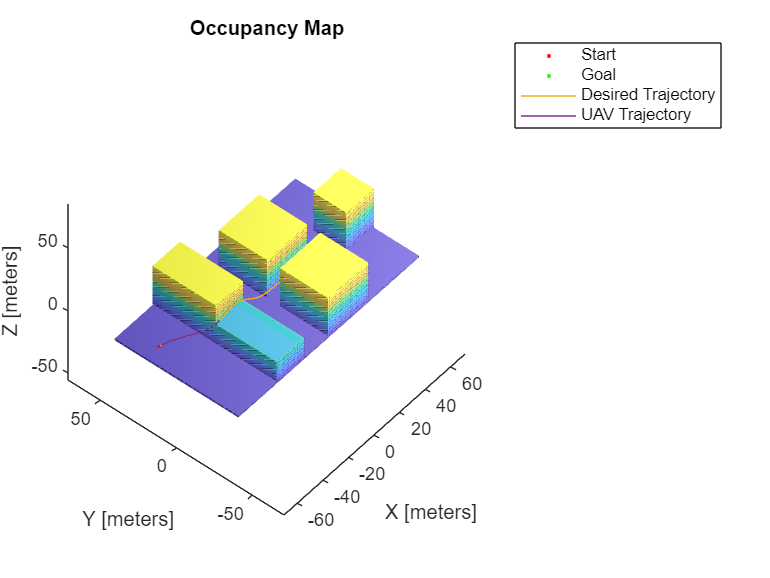

%System trajectory:
system_trajectory=nan(3,length(simout.p_b_i.time));
system_velocity=nan(3,length(simout.v_i.time));
for i=1:length(simout.p_b_i.time)
    system_trajectory(:,i)=simout.p_b_i.data(:,1,i);
    system_velocity(:,i)=simout.v_i.data(:,1,i);
end

%Desired trajectory
desired_trajectory=nan(3,length(simout.p_d.time));
desired_velocity=nan(3,length(simout.v_d.time));
for i=1:length(simout.p_b_i.time)
    desired_trajectory(:,i)=simout.p_d.data(:,1,i);
    desired_velocity(:,i)=simout.v_d.data(:,1,i);
end

figure
clf 
show(map3D)
hold on 
scatter3(startState(1),startState(2),startState(3),30,".r")
scatter3(goalState(1),goalState(2),goalState(3),30,".g")
plot3(desired_trajectory(1,:),desired_trajectory(2,:),desired_trajectory(3,:))
plot3(system_trajectory(1,:),system_trajectory(2,:),system_trajectory(3,:))
legend("","Start","Goal","Desired Trajectory","UAV Trajectory")

Provide a quantitative assessment of the error in position and velocity. 

T=55; %[s] Simulation time
pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    pos_integrand(i)=(system_trajectory(:,i)-desired_trajectory(:,i))'*(system_trajectory(:,i)-desired_trajectory(:,i));
end

for i=1:length(simout.v_i.time)
    vel_integrand(i)=(system_velocity(:,i)-desired_velocity(:,i))'*(system_velocity(:,i)-desired_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.1225

display(vel_Error)

vel_Error = 0.0879

With wind, the trajectories are identical at a large scale but the position error increases noticeably, while the velocity error experiences a small increase. 

## Baseline Controller with control degradation: 

#### Flight Simulation: 

Specify control degradation: 

%Turn off switches
degradation_switch=1;
wind_switch=0;
Lambda_deg=0.8*eye(6,6);
t_deg=30;
w_intensity=5; %[m/s], quite intense

%Specify baseline Lambda:
Lambda_baseline=eye(6,6);

Simulate flight: 

simout=sim("Flight_Test_Baseline_Model.slx","StopTime",'55','RelTol','1e-6');

#### Simulation Postprocessing: 

Begin by plotting the desired and flown trajectories together for a qualitative assessment. 

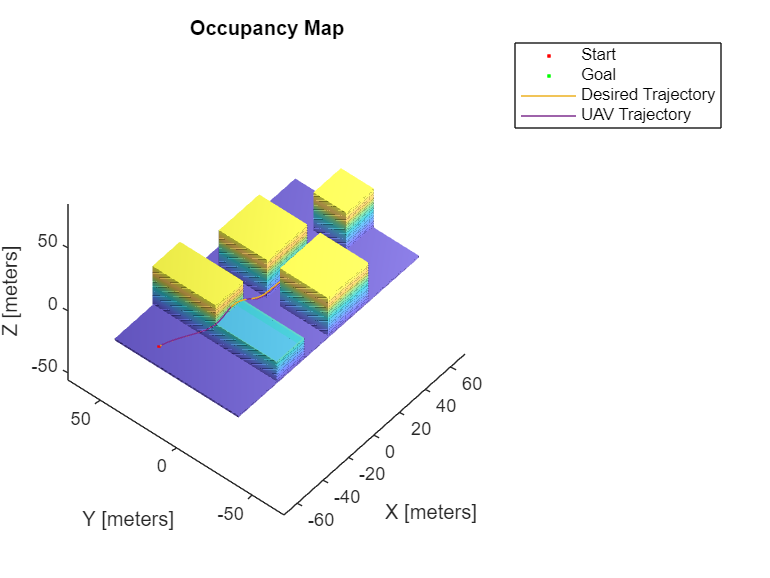

%System trajectory:
system_trajectory=nan(3,length(simout.p_b_i.time));
system_velocity=nan(3,length(simout.v_i.time));
for i=1:length(simout.p_b_i.time)
    system_trajectory(:,i)=simout.p_b_i.data(:,1,i);
    system_velocity(:,i)=simout.v_i.data(:,1,i);
end

%Desired trajectory
desired_trajectory=nan(3,length(simout.p_d.time));
desired_velocity=nan(3,length(simout.v_d.time));
for i=1:length(simout.p_b_i.time)
    desired_trajectory(:,i)=simout.p_d.data(:,1,i);
    desired_velocity(:,i)=simout.v_d.data(:,1,i);
end

figure
clf 
show(map3D)
hold on 
scatter3(startState(1),startState(2),startState(3),30,".r")
scatter3(goalState(1),goalState(2),goalState(3),30,".g")
plot3(desired_trajectory(1,:),desired_trajectory(2,:),desired_trajectory(3,:))
plot3(system_trajectory(1,:),system_trajectory(2,:),system_trajectory(3,:))
legend("","Start","Goal","Desired Trajectory","UAV Trajectory")

Provide a quantitative assessment of the error in position and velocity. 

T=55; %[s] Simulation time
pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    pos_integrand(i)=(system_trajectory(:,i)-desired_trajectory(:,i))'*(system_trajectory(:,i)-desired_trajectory(:,i));
end

for i=1:length(simout.v_i.time)
    vel_integrand(i)=(system_velocity(:,i)-desired_velocity(:,i))'*(system_velocity(:,i)-desired_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.5399

display(vel_Error)

vel_Error = 0.1188

With a degradation in control effectiveness, the position error grows a lot and it can be noticeable at some points in the trajectory (look at the turn at the end of the hump). The velocity error also increases. 

## Baseline Controller with control degradation and wind: 

#### Flight Simulation: 

Specify windy conditions and control degradation: 

%Turn off switches
degradation_switch=1;
wind_switch=1;
Lambda_deg=0.8*eye(6,6);
t_deg=30;
w_intensity=5; %[m/s], quite intense

%Specify baseline Lambda:
Lambda_baseline=eye(6,6);

Simulate flight: 

simout=sim("Flight_Test_Baseline_Model.slx","StopTime",'55','RelTol','1e-6');

#### Simulation Postprocessing: 

Begin by plotting the desired and flown trajectories together for a qualitative assessment. 

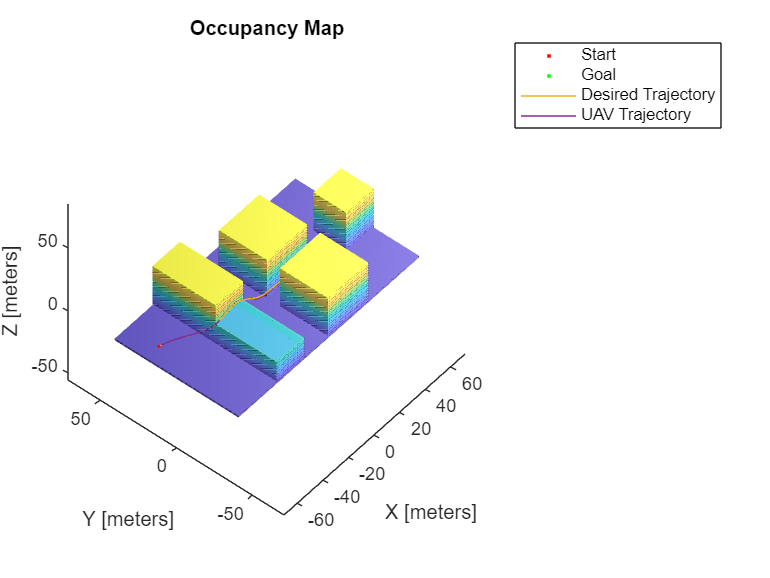

%System trajectory:
system_trajectory=nan(3,length(simout.p_b_i.time));
system_velocity=nan(3,length(simout.v_i.time));
for i=1:length(simout.p_b_i.time)
    system_trajectory(:,i)=simout.p_b_i.data(:,1,i);
    system_velocity(:,i)=simout.v_i.data(:,1,i);
end

%Desired trajectory
desired_trajectory=nan(3,length(simout.p_d.time));
desired_velocity=nan(3,length(simout.v_d.time));
for i=1:length(simout.p_b_i.time)
    desired_trajectory(:,i)=simout.p_d.data(:,1,i);
    desired_velocity(:,i)=simout.v_d.data(:,1,i);
end

figure
clf 
show(map3D)
hold on 
scatter3(startState(1),startState(2),startState(3),30,".r")
scatter3(goalState(1),goalState(2),goalState(3),30,".g")
plot3(desired_trajectory(1,:),desired_trajectory(2,:),desired_trajectory(3,:))
plot3(system_trajectory(1,:),system_trajectory(2,:),system_trajectory(3,:))
legend("","Start","Goal","Desired Trajectory","UAV Trajectory")

Provide a quantitative assessment of the error in position and velocity. 

T=55; %[s] Simulation time
pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    pos_integrand(i)=(system_trajectory(:,i)-desired_trajectory(:,i))'*(system_trajectory(:,i)-desired_trajectory(:,i));
end

for i=1:length(simout.v_i.time)
    vel_integrand(i)=(system_velocity(:,i)-desired_velocity(:,i))'*(system_velocity(:,i)-desired_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.5454

display(vel_Error)

vel_Error = 0.1201

The situation doesn't change much with respect to the case with only control efficiency degradation. Now that the baseline system has been studied, it's time to compare it with the augmented model and see the difference. 

## Adaptive Controller in Nominal Conditions: 

#### Flight Simulation: 

Specify nominal conditions: 

%Turn off switches
degradation_switch=0;
wind_switch=0;
Lambda_deg=eye(6,6);
t_deg=1;
w_intensity=0;

%Specify baseline Lambda:
Lambda_baseline=eye(6,6);

Simulate flight: 

simout=sim("Flight_Test_Augmented_Model.slx","StopTime",'55','RelTol','1e-6');

#### Simulation Postprocessing: 

Begin by plotting the desired and flown trajectories together for a qualitative assessment. 

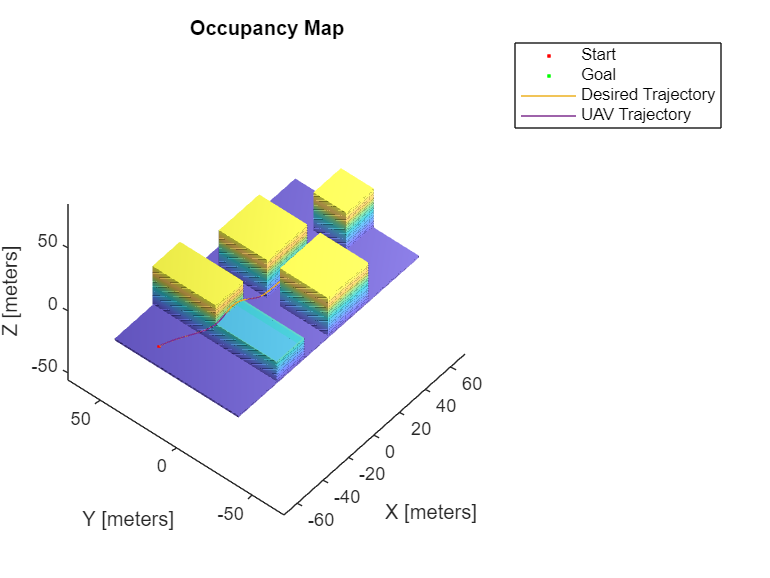

%System trajectory:
system_trajectory=nan(3,length(simout.p_b_i.time));
system_velocity=nan(3,length(simout.v_i.time));
for i=1:length(simout.p_b_i.time)
    system_trajectory(:,i)=simout.p_b_i.data(:,1,i);
    system_velocity(:,i)=simout.v_i.data(:,1,i);
end

%Desired trajectory
desired_trajectory=nan(3,length(simout.p_d.time));
desired_velocity=nan(3,length(simout.v_d.time));
for i=1:length(simout.p_b_i.time)
    desired_trajectory(:,i)=simout.p_d.data(:,1,i);
    desired_velocity(:,i)=simout.v_d.data(:,1,i);
end

figure
clf 
show(map3D)
hold on 
scatter3(startState(1),startState(2),startState(3),30,".r")
scatter3(goalState(1),goalState(2),goalState(3),30,".g")
plot3(desired_trajectory(1,:),desired_trajectory(2,:),desired_trajectory(3,:))
plot3(system_trajectory(1,:),system_trajectory(2,:),system_trajectory(3,:))
legend("","Start","Goal","Desired Trajectory","UAV Trajectory")

Provide a quantitative assessment of the error in position and velocity. 

T=55; %[s] Simulation time
pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    pos_integrand(i)=(system_trajectory(:,i)-desired_trajectory(:,i))'*(system_trajectory(:,i)-desired_trajectory(:,i));
end

for i=1:length(simout.v_i.time)
    vel_integrand(i)=(system_velocity(:,i)-desired_velocity(:,i))'*(system_velocity(:,i)-desired_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.0517

display(vel_Error)

vel_Error = 0.0816

Under nominal flight conditions, the adaptive augmentation of the controller leads to a significant decrease in position error (about 50%) and a noticeable, but not too great, decrease in velocity error. 

## Adaptive Controller with wind:  

#### Flight Simulation: 

Specify windy conditions: 

%Turn off switches
degradation_switch=0;
wind_switch=1;
Lambda_deg=eye(6,6);
t_deg=1;
w_intensity=5; %[m/s], quite intense

%Specify baseline Lambda:
Lambda_baseline=eye(6,6);

Simulate flight: 

simout=sim("Flight_Test_Augmented_Model.slx","StopTime",'55','RelTol','1e-6');

#### Simulation Postprocessing: 

Begin by plotting the desired and flown trajectories together for a qualitative assessment. 

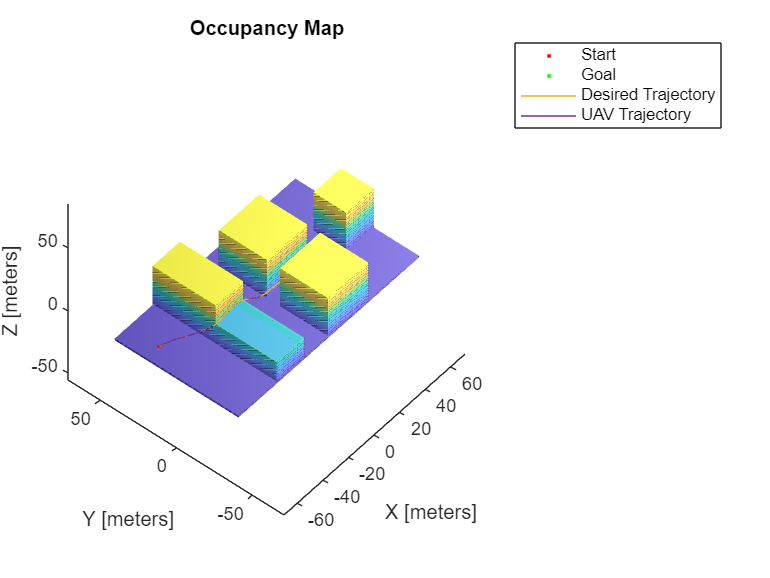

%System trajectory:
system_trajectory=nan(3,length(simout.p_b_i.time));
system_velocity=nan(3,length(simout.v_i.time));
for i=1:length(simout.p_b_i.time)
    system_trajectory(:,i)=simout.p_b_i.data(:,1,i);
    system_velocity(:,i)=simout.v_i.data(:,1,i);
end

%Desired trajectory
desired_trajectory=nan(3,length(simout.p_d.time));
desired_velocity=nan(3,length(simout.v_d.time));
for i=1:length(simout.p_b_i.time)
    desired_trajectory(:,i)=simout.p_d.data(:,1,i);
    desired_velocity(:,i)=simout.v_d.data(:,1,i);
end

figure
clf 
show(map3D)
hold on 
scatter3(startState(1),startState(2),startState(3),30,".r")
scatter3(goalState(1),goalState(2),goalState(3),30,".g")
plot3(desired_trajectory(1,:),desired_trajectory(2,:),desired_trajectory(3,:))
plot3(system_trajectory(1,:),system_trajectory(2,:),system_trajectory(3,:))
legend("","Start","Goal","Desired Trajectory","UAV Trajectory")

Provide a quantitative assessment of the error in position and velocity. 

T=55; %[s] Simulation time
pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    pos_integrand(i)=(system_trajectory(:,i)-desired_trajectory(:,i))'*(system_trajectory(:,i)-desired_trajectory(:,i));
end

for i=1:length(simout.v_i.time)
    vel_integrand(i)=(system_velocity(:,i)-desired_velocity(:,i))'*(system_velocity(:,i)-desired_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.0529

display(vel_Error)

vel_Error = 0.0822

Under windy conditions, the adaptive controller is better able to adapt to the new conditions, which leads to smaller position error and a smaller increase in position error when compared with the baseline case. In terms of velocity, error is lower, but the increase is comparable. 

## Adaptive Controller with control degradation:  

#### Flight Simulation: 

Specify control degradation: 

%Turn off switches
degradation_switch=1;
wind_switch=0;
Lambda_deg=0.8*eye(6,6);
t_deg=30;
w_intensity=5; %[m/s], quite intense

%Specify baseline Lambda:
Lambda_baseline=eye(6,6);

Simulate flight: 

simout=sim("Flight_Test_Augmented_Model.slx","StopTime",'55','RelTol','1e-6');

#### Simulation Postprocessing: 

Begin by plotting the desired and flown trajectories together for a qualitative assessment. 

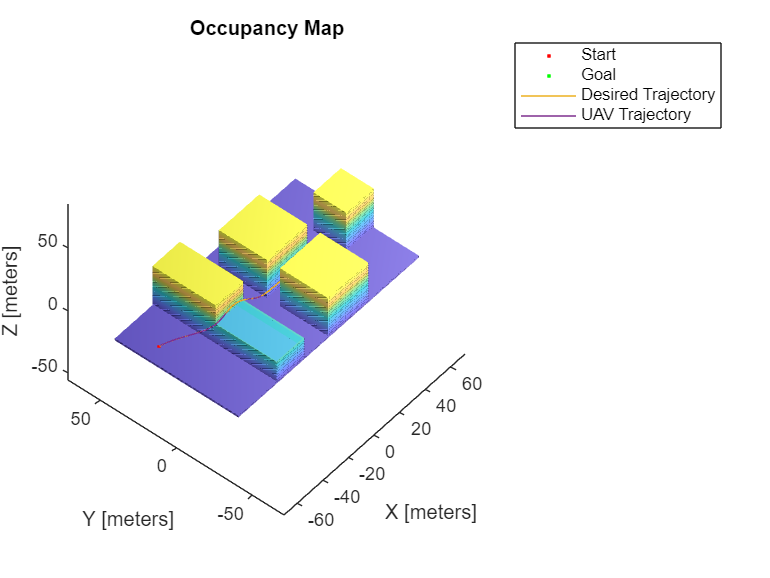

%System trajectory:
system_trajectory=nan(3,length(simout.p_b_i.time));
system_velocity=nan(3,length(simout.v_i.time));
for i=1:length(simout.p_b_i.time)
    system_trajectory(:,i)=simout.p_b_i.data(:,1,i);
    system_velocity(:,i)=simout.v_i.data(:,1,i);
end

%Desired trajectory
desired_trajectory=nan(3,length(simout.p_d.time));
desired_velocity=nan(3,length(simout.v_d.time));
for i=1:length(simout.p_b_i.time)
    desired_trajectory(:,i)=simout.p_d.data(:,1,i);
    desired_velocity(:,i)=simout.v_d.data(:,1,i);
end

figure
clf 
show(map3D)
hold on 
scatter3(startState(1),startState(2),startState(3),30,".r")
scatter3(goalState(1),goalState(2),goalState(3),30,".g")
plot3(desired_trajectory(1,:),desired_trajectory(2,:),desired_trajectory(3,:))
plot3(system_trajectory(1,:),system_trajectory(2,:),system_trajectory(3,:))
legend("","Start","Goal","Desired Trajectory","UAV Trajectory")

Provide a quantitative assessment of the error in position and velocity. 

T=55; %[s] Simulation time
pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    pos_integrand(i)=(system_trajectory(:,i)-desired_trajectory(:,i))'*(system_trajectory(:,i)-desired_trajectory(:,i));
end

for i=1:length(simout.v_i.time)
    vel_integrand(i)=(system_velocity(:,i)-desired_velocity(:,i))'*(system_velocity(:,i)-desired_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.0568

display(vel_Error)

vel_Error = 0.0823

In this case, the capabilities of adaptive control become apparent. Not only are errors significantly smaller (particularly in position) when compared to the baseline case, but the increase in error caused by the loss of control effectiveness is greatly reduced. In other words, the system is able to adapt to the changing conditions and mitigate the performance loss.

## Adaptive Controller with control degradation and wind:  

#### Flight Simulation: 

Specify windy conditions and control degradation: 

%Turn off switches
degradation_switch=1;
wind_switch=1;
Lambda_deg=0.8*eye(6,6);
t_deg=30;
w_intensity=5; %[m/s], quite intense

%Specify baseline Lambda:
Lambda_baseline=eye(6,6);

Simulate flight: 

simout=sim("Flight_Test_Augmented_Model.slx","StopTime",'55','RelTol','1e-6');

#### Simulation Postprocessing: 

Begin by plotting the desired and flown trajectories together for a qualitative assessment. 

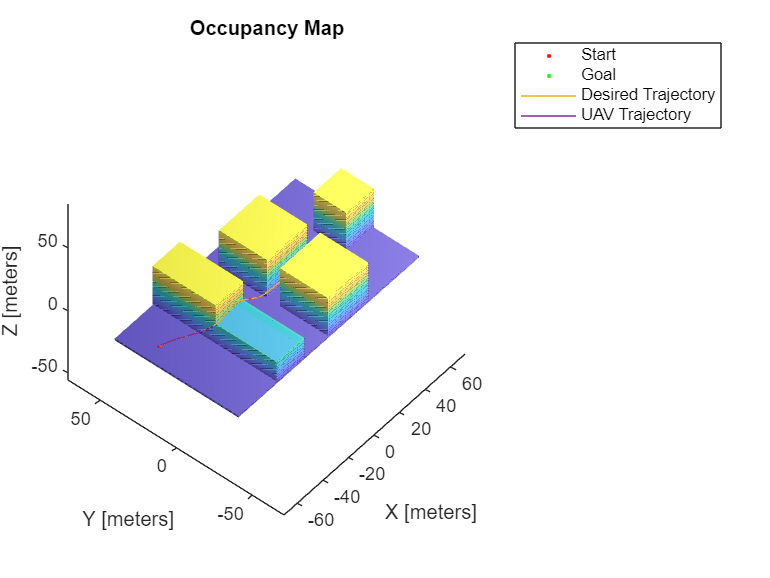

%System trajectory:
system_trajectory=nan(3,length(simout.p_b_i.time));
system_velocity=nan(3,length(simout.v_i.time));
for i=1:length(simout.p_b_i.time)
    system_trajectory(:,i)=simout.p_b_i.data(:,1,i);
    system_velocity(:,i)=simout.v_i.data(:,1,i);
end

%Desired trajectory
desired_trajectory=nan(3,length(simout.p_d.time));
desired_velocity=nan(3,length(simout.v_d.time));
for i=1:length(simout.p_b_i.time)
    desired_trajectory(:,i)=simout.p_d.data(:,1,i);
    desired_velocity(:,i)=simout.v_d.data(:,1,i);
end

figure
clf 
show(map3D)
hold on 
scatter3(startState(1),startState(2),startState(3),30,".r")
scatter3(goalState(1),goalState(2),goalState(3),30,".g")
plot3(desired_trajectory(1,:),desired_trajectory(2,:),desired_trajectory(3,:))
plot3(system_trajectory(1,:),system_trajectory(2,:),system_trajectory(3,:))
legend("","Start","Goal","Desired Trajectory","UAV Trajectory")

Provide a quantitative assessment of the error in position and velocity. 

T=55; %[s] Simulation time
pos_integrand=nan(1,length(simout.p_b_i.time));
vel_integrand=nan(1,length(simout.v_i.time));

for i=1:length(simout.p_b_i.time)
    pos_integrand(i)=(system_trajectory(:,i)-desired_trajectory(:,i))'*(system_trajectory(:,i)-desired_trajectory(:,i));
end

for i=1:length(simout.v_i.time)
    vel_integrand(i)=(system_velocity(:,i)-desired_velocity(:,i))'*(system_velocity(:,i)-desired_velocity(:,i));
end


pos_Error=sqrt(1/T*(trapz(simout.p_b_i.time',pos_integrand)));
vel_Error=sqrt(1/T*(trapz(simout.p_b_i.time',vel_integrand)));

display(pos_Error)

pos_Error = 0.0574

display(vel_Error)

vel_Error = 0.0828

The results seen for the adaptive controller heretofore still apply in this case. The controller is able to adapt and greatly reduce the increase in velocity and position error caused by the unforeseen events. This, coupled with an already better initial performance, leads to much better results than those obtained with the baseline controller. 

## Comparison Plot for Presentation:

Consider the case of wind and control degradation and plot the trajectories of the baseline and adaptive controllers. 

### Baseline system: 

#### Flight Simulation: 

Specify windy conditions and control degradation: 

%Turn off switches
degradation_switch=1;
wind_switch=1;
Lambda_deg=0.8*eye(6,6);
t_deg=30;
w_intensity=5; %[m/s], quite intense

%Specify baseline Lambda:
Lambda_baseline=eye(6,6);

Simulate flight: 

simout=sim("Flight_Test_Baseline_Model.slx","StopTime",'55','RelTol','1e-6');

#### Simulation Postprocessing: 

Begin by plotting the desired and flown trajectories together for a qualitative assessment. 

%System trajectory:
baseline_trajectory=nan(3,length(simout.p_b_i.time));
for i=1:length(simout.p_b_i.time)
    baseline_trajectory(:,i)=simout.p_b_i.data(:,1,i);
end

%Desired trajectory
desired_trajectory=nan(3,length(simout.p_d.time));
for i=1:length(simout.p_b_i.time)
    desired_trajectory(:,i)=simout.p_d.data(:,1,i);
end

### Augmented System: 

#### Flight Simulation: 

Specify windy conditions and control degradation: 

%Turn off switches
degradation_switch=1;
wind_switch=1;
Lambda_deg=0.8*eye(6,6);
t_deg=30;
w_intensity=5; %[m/s], quite intense

%Specify baseline Lambda:
Lambda_baseline=eye(6,6);

Simulate flight: 

simout=sim("Flight_Test_Augmented_Model.slx","StopTime",'55','RelTol','1e-6');

#### Simulation Postprocessing: 

Begin by plotting the desired and flown trajectories together for a qualitative assessment. 

%System trajectory:
augmented_trajectory=nan(3,length(simout.p_b_i.time));
for i=1:length(simout.p_b_i.time)
    augmented_trajectory(:,i)=simout.p_b_i.data(:,1,i);
end

### Comparative plot: 

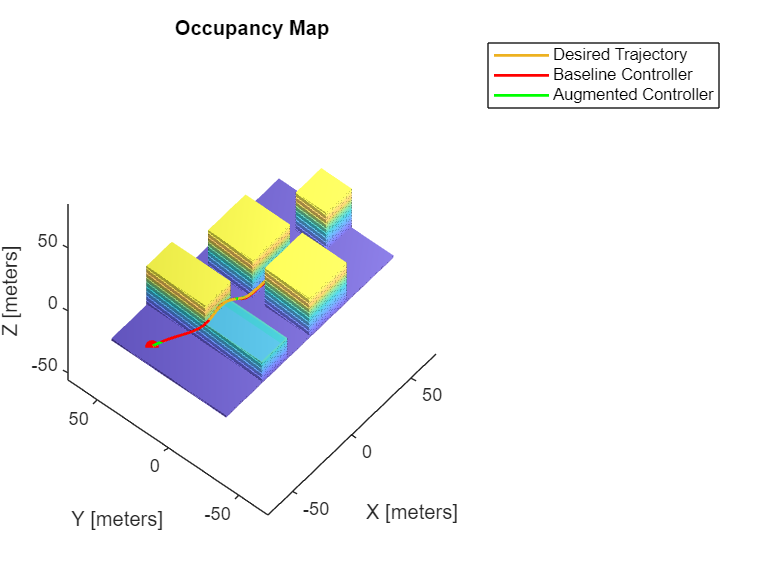

figure
clf 
show(map3D)
hold on 
scatter3(startState(1),startState(2),startState(3),500,".r")
scatter3(goalState(1),goalState(2),goalState(3),500,".g")
plot3(desired_trajectory(1,:),desired_trajectory(2,:),desired_trajectory(3,:),'LineWidth',1.5)
plot3(baseline_trajectory(1,:),baseline_trajectory(2,:),baseline_trajectory(3,:),'r','LineWidth',1.5)
plot3(augmented_trajectory(1,:),augmented_trajectory(2,:),augmented_trajectory(3,:),'g','LineWidth',1.5)
legend("","","","Desired Trajectory","Baseline Controller","Augmented Controller")